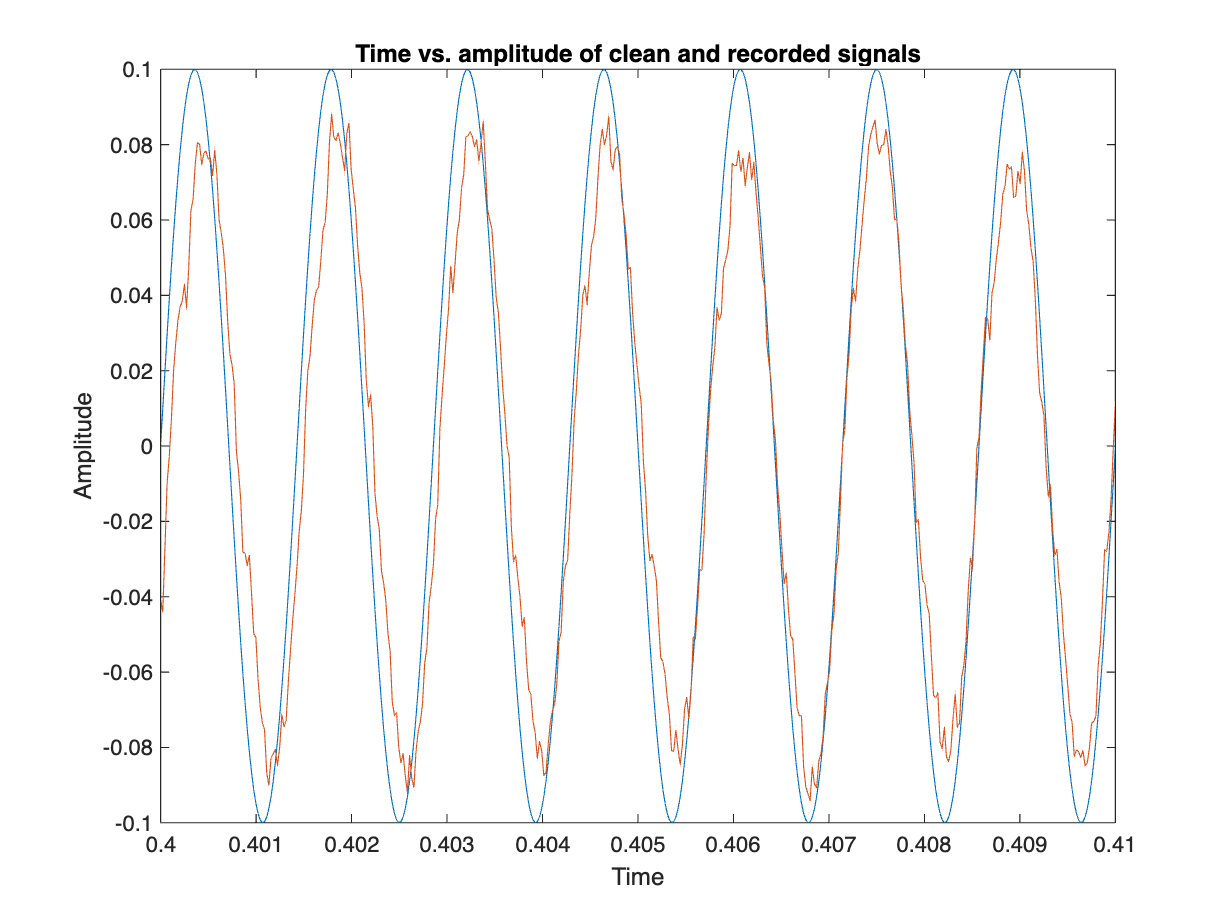

% Generation of the clean 700 Hz signal
fs = 44100;
T = 0.5;
t = 0:1/fs:T;
clean_signal = 0.1 * sin(700 * 2 * pi * t); % decreased amplitude so that it's similar to the voice signal amplitude

% Now we need to load the voice signal
path = ['/Users', filesep, 'nehalsharma', filesep, 'Downloads', filesep];	
filename = 'voice.wav'; 
[voice_signal, fs_y] = audioread([path, filename]);

% Now we plot them both : first the clean signal
figure('Name','Figure 1 : Pure and voice signal at 700 Hz');
plot(t,clean_signal, '-');
xlabel('Time');
ylabel('Amplitude');
xlim([0.40 0.41]);

% Now the voice signal
hold on;
voice_signal = [voice_signal; 0];
t_voice = (0:length(voice_signal)-1)/fs_y;
plot(t_voice, voice_signal);
title('Time vs. amplitude of clean and recorded signals');
hold off;

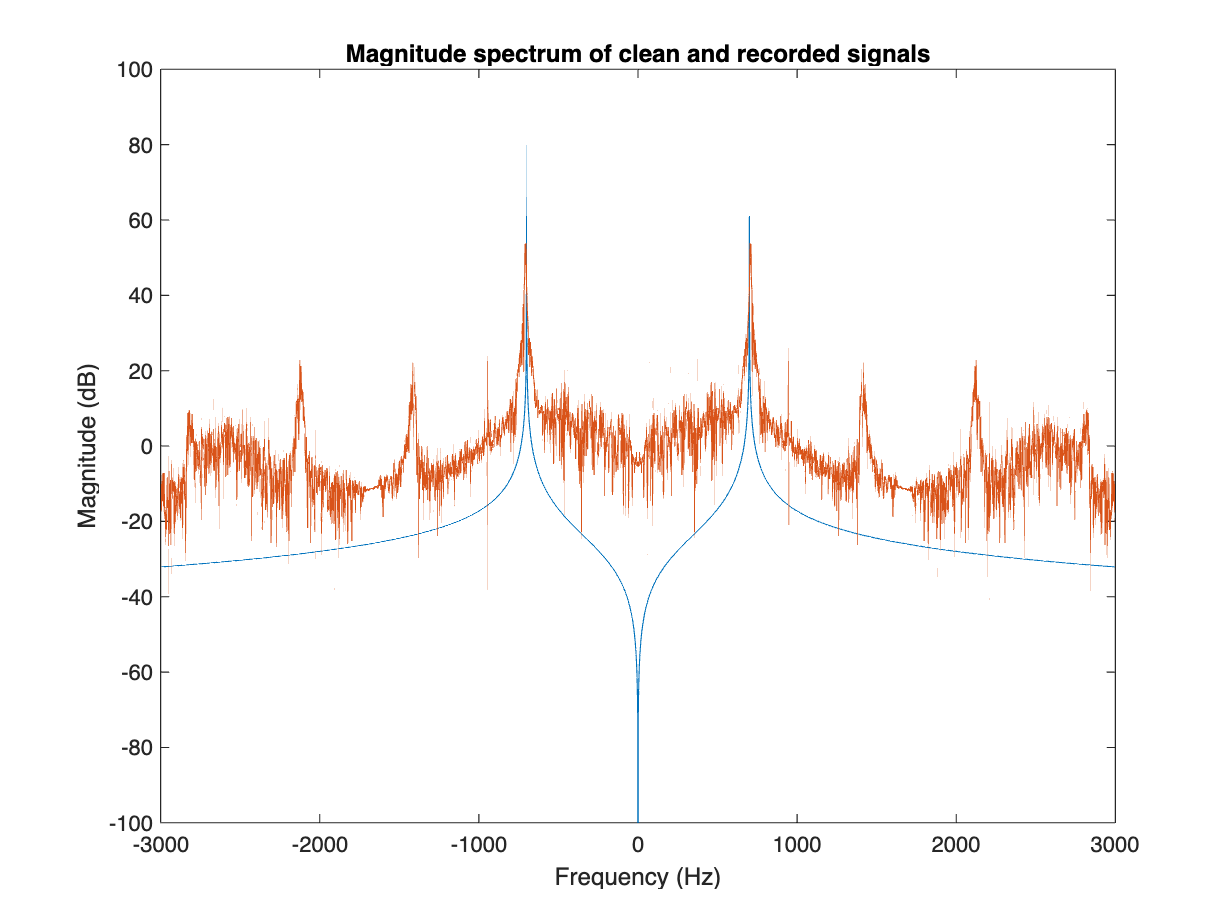

%%

F0 = 2;
CLEAN_SIGNAL = fft(clean_signal);
VOICE_SIGNAL = fft(voice_signal);

N_clean = length(clean_signal);  
Y_shifted_clean = fftshift(CLEAN_SIGNAL);   % Shifts zero-frequency component to the center

N_voice = length(voice_signal);
Y_shifted_voice = fftshift(VOICE_SIGNAL);

% Frequency vector (positive and negative frequencies)
f_pos = 0:F0:(fs/2);
f_neg = -fs/2:F0:-F0; 
f = linspace(-fs/2, fs/2, N_clean);

% Plot the magnitude spectrum in dB
figure;
plot(f, 20 * log10(abs(Y_shifted_clean)));  % Plot in dB scale
hold on;
plot(f, 20 * log10(abs(Y_shifted_voice)));
xlim([-3000 3000]);
ylim([-100 100]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude spectrum of clean and recorded signals');